# Week of September 23rd

#### By Bora Basyildiz 

## I. Interpolation Integration 

For this week, I used the interpolation  integration provided by Professor Strong, and I worked with this code in two separate ways. First, I compared its outputs to the integration from the *trapz* function. First, I observed that the outputs from the same set of values and points were different. For the BSI impact on the same point, we the following values 

p = [-1;0;0];
C1 = Curve_Gen('circle',500);
s = 1:length(C1); 
T1 = Derivative(C1); 
Biot_Savart(C1,T1,p,0)

ans = 1.0e+02 *

   1.760800282941242
   0.003535884216204
  -0.000022261726209


Scott_Integral

ans =      0


ans =      3.847964436005157e-04


ans =     -4.844696998885793e-06


First, we note that both the Biot_Savart integral and Scott_Integral has different directions and magnitudes. I tried to look into the difference for this, but I am still new to the interpolation code. I will likely have to sit down with Professor Strong to discuss why this might be the case. This difference in values is troubling, and merits more discussion on which value is correct. 

I also implemented the Interpolation Integration into the Curve_Evol 

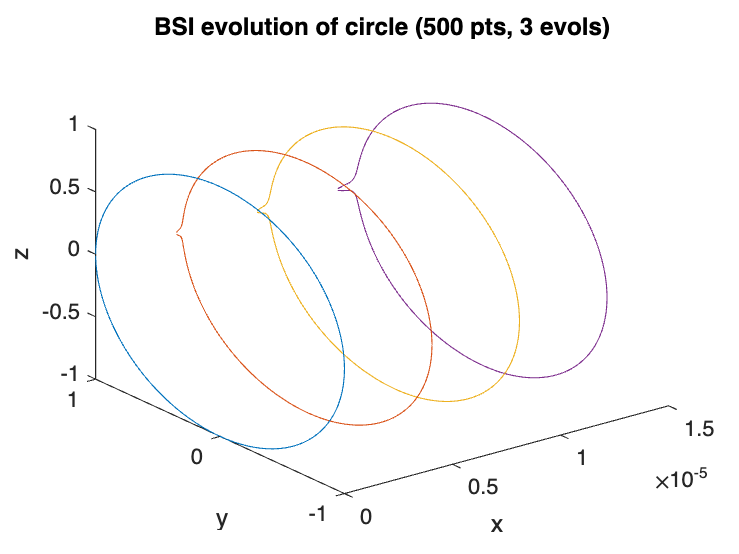

Curve_Evol('circle','BSI',500,3)

I saw that the only impact that the interpolation integration had was on points near the origin. I shifted the integration domain such that each point is integrating on its nearest components, but still, this problem consisted. It is yet to be seen whether this issue is systemic or an implemention issue. 

## II. Implicit Evolution 

Previously we discussed using the RK4 method to enable implicit method like the Adam Bashforth method. I reworked the Curve_Evol function to account for this, and used the Adams Bashforth 4 (AB4) for our implciit evolution. For the first we timesteps we cannot use AB4, and for those I purely use RK4. This unbelievably, makes our method highly stable! We are now able to have evolutions of 50-70 with many of our methods. Methods like the base kappa Binormal diverege quicker than methods like the kappa Binormal expansion. Similarly, the BSI method is highly stable, but the small error created by the integration error caps the BSI evolution under 100 cycles. However, even with this error and a small number of points, we can have high amounts of evolution. See below

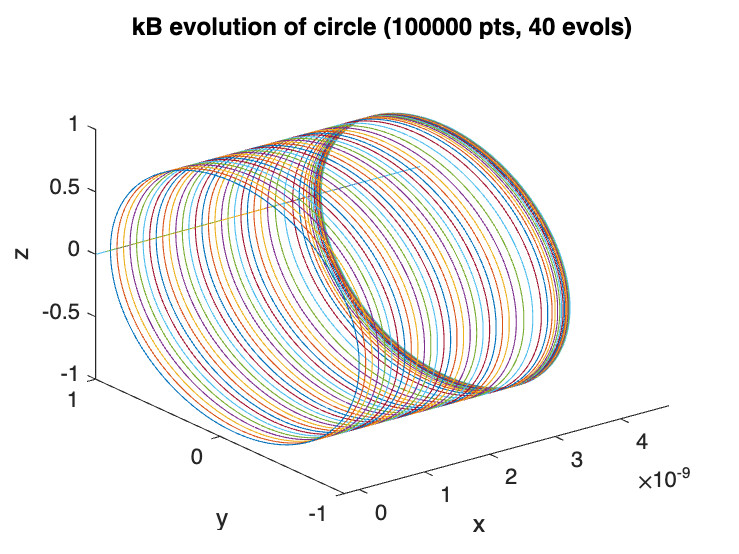

Curve_Evol('circle','kB',100000,40)

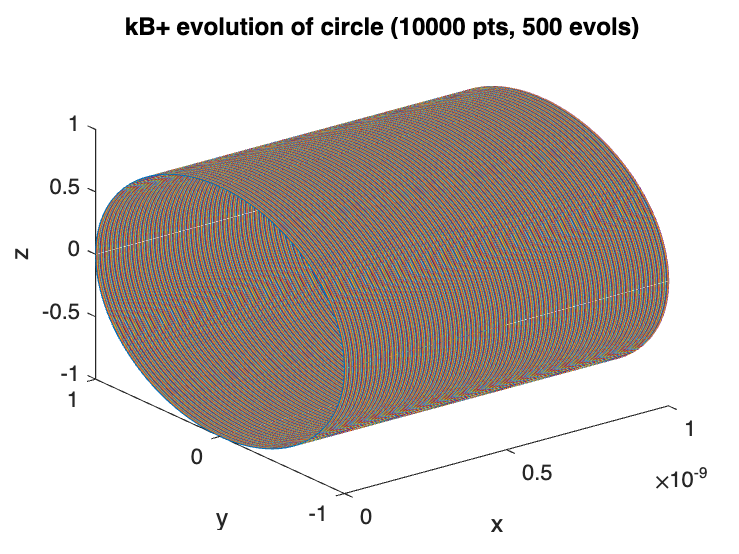

Curve_Evol('circle','kB+',10000,500)

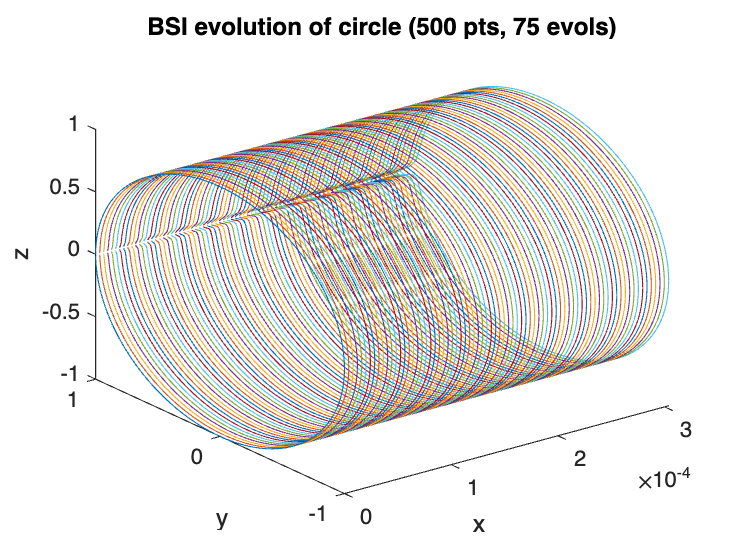

Curve_Evol('circle','BSI',500,75)

Even though there are small k sizes, we can increase the k size very well for the kappa Binormal Expansion and Biot Savart Integral. However, this is not the case for the kappa Binormal evolution, as it diverges with 20 evolutions for non-tiny k sizes.

## IV. Future Thoughts

Due to the implicit method evolution, it seems as though our Curve evolution is near finished. However a few steps still remain. On the development side, the integration error for the Biot Savart needs to be fixed through either the flip method, interpolation, or monte carlo integration. Also, the development of the rough ring and circle soliton need to be developed. Lastly, there is a bizarre error with the evolution of the soliton and the kappa Binormal methods that needs to be addressed. However, I am excited for the direction of this research, and hopefully we produce results soon! 